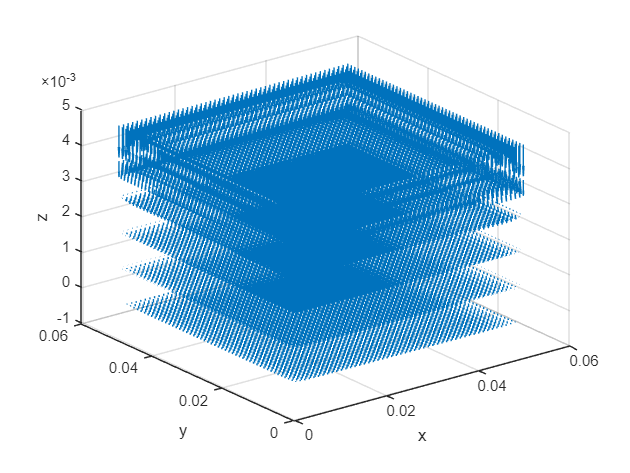

% A computational tool to calculate the capacitance of a 3D rectangular prism composed of two plates parallel to x-y plane

clear;
clc;

% Grid dimensions - number of points
xdim=50;
ydim=50;
zdim=5;
dx = 0.001;             % grid spacing (1 mm, arbitrary scaling)
dy = 0.001;
dz = 0.001;

% Initialize voltage matricies
V_now=zeros(xdim+1, ydim+1, zdim+1);

% Initialize boundary conditions (capacitor plates)
V_top = 30;
V_now(:, :, 1) = 0;          % bottom plate 0V (bottom plate is z = 0)
V_now(:, :, zdim+1) = V_top;    % top plate 10V

% Iteration counter
iter=0;

% Calculation of maximum error between V_now and V_prev at all points
% by setting the applied voltage for only V_now, we have made V_no and
% V_prev different, hence error will be greater than zero and the program
% will enter the while loop following this command.
V_prev = V_now;
error=1;%max(max(abs(V_now-V_prev)));

% Iteration loop
while(error>0.01)%Run this until convergence
    
    iter=iter+1; % Iteration counter increment
    
    % Updating present iteration using 6? point Central diffrence form
    % of Laplace equation obtained using Finite Difference method
    for i = 2:xdim
        for j = 2:ydim
            for k = 2:zdim
                V_now(i, j, k) = (V_prev(i-1, j, k)+V_prev(i+1, j, k)+V_prev(i, j-1, k)+V_prev(i, j+1, k)+V_prev(i, j, k-1)+V_prev(i, j, k+1))/6;
            end
        end
    end
    % enforce boundary conditions on feach iteration
    V_now(:,:,1)       = 0;
    V_now(:,:,zdim+1)  = V_top;

    error=max(max(abs(V_now(:)-V_prev(:)))); % Calculate the maximum error between previous and current iteration at all points
    V_prev=V_now; % Updating previous iteration matrix to the last iteration performed
    
    % Add visualization from BDE solver here if have time

    %Movie type colour scaled image plot to see how solution progresses
    % visualize middle plane
    % if mod(iter,10)==0
    %     imagesc(V_now(:,:,round(zdim/2)));
    %     colorbar;
    %     title(['Iteration ', int2str(iter), ', error=', num2str(error)]);
    %     drawnow;
    % end
    %imagesc(V_now);colorbar;
    %title(['Voltage distribution on a ',int2str(xdim),' x ',int2str(ydim),' x ', int2str(zdim), ' mesh at iteration no ',int2str(iter)],'Color','k'); 
    %getframe;
end

% Plot the electric field distribution
figure;
[ex, ey, ez]=gradient(V_now, dx, dy, dz); % E, electric field
ex = -ex;
ey = -ey;
ez = -ez;
[x, y, z] = meshgrid((0:size(V_now, 2)-1)*dx, (0:size(V_now,1)-1)*dy, (0:size(V_now,3)-1)*dz);
quiver3(x, y, z, ex, ey, ez); % quiver3 command creates a plot of E=-grad(V)
xlabel('x'); ylabel('y'); zlabel('z')


%Calculate capacitance
epsilon0 = 8.854e-12;           % Air permittivity
Ex_top = -ex(:, :, end-1);      % x component of field just below the top (charged) plate
Ey_top = -ey(:, :, end-1);      % y component of field just below the top (charged) plate
Ez_top = -ez(:,:,end-1);        % z component of field just below the top (charged) plate
rho = epsilon0 * Ez_top;        % surface charge density (C/m^2)
Q_top = sum(rho)*dx*dy;         % integrate over plate area
Q_tot = sum(Q_top(:));
C = Q_tot/V_top;
A = (xdim*dx) * (ydim*dy); % plate area
C_theoretical = epsilon0 * A / (zdim*dz); % for testing purposes
